clear;

load('par.mat')

syms g mb rb Jb Jp dt
% g is the gravitational acceleration
% mb is mass of the ball
% rb is the radius of the ball 
% Jb is the ball's moment of inertia 
% Jp s the plates moment of inertia 

# **Flatness based controller design for a ball on a plate**

# Exercise 5.1

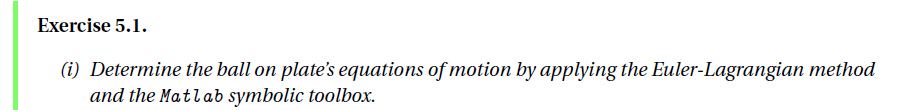

**Generalized coordinates**

syms x_x(t) x_y(t) phi_x(t) phi_y(t)

% q denotes the generalized coordinates and q_dot denotes the generalized velocities.
q = [ x_x(t) x_y(t) phi_x(t) phi_y(t) ];
q_dot = diff(q,t);

**Kinetic Energy**

% For the ball, the kinetic energy consists of a translational and a rotatory component.
W_kin_trans_b = 0.5*mb*( q_dot(1)^2 + q_dot(2)^2 );
W_kin_rot_b = 0.5*(Jb/(rb^2))*( q_dot(1)^2 + q_dot(2)^2 );
W_kin_b = W_kin_trans_b + W_kin_rot_b;

% The balls moment of inertia can be described by Jb = 2/5 mb rb^2
W_kin_b = subs(W_kin_b, Jb, (2/5)*mb*rb^2)

$$W\_kin\_b = \frac{7\,\mathrm{mb}\,\left({\left(\frac{\partial }{\partial t}x_{x}\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}x_{y}\left(t\right)\right)}^{2}\right)}{10}$$


% For the plate, the kinetic energy of the plate is given by its rotational energy
W_kin_p = 0.5*(Jb+Jp)*( q_dot(3)^2 + q_dot(4)^2 ) + 0.5*mb*( q(1)*q_dot(3) + q(2)*q_dot(4) )^2

$$W\_kin\_p = \frac{\mathrm{mb}\,{\left(x_{x}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{x}\left(t\right)+x_{y}\left(t\right)\,\frac{\partial }{\partial t}\varphi_{y}\left(t\right)\right)}^{2}}{2}+\left({\left(\frac{\partial }{\partial t}\varphi_{x}\left(t\right)\right)}^{2}+{\left(\frac{\partial }{\partial t}\varphi_{y}\left(t\right)\right)}^{2}\right)\,\left(\frac{\mathrm{Jb}}{2}+\frac{\mathrm{Jp}}{2}\right)$$


% The total kinetic energy
W_kin = W_kin_p + W_kin_b;

**Potential Energy**

% The potential energy of the system
W_pot = mb*g*( q(1)*sin(q(3)) + q(2)*sin(q(4)) )

$$W\_pot = g\,\mathrm{mb}\,\left(\sin\left(\varphi_{x}\left(t\right)\right)\,x_{x}\left(t\right)+\sin\left(\varphi_{y}\left(t\right)\right)\,x_{y}\left(t\right)\right)$$

**Generalized forces**

syms tau_x tau_y

% Q denotes our generalized forces
Q = [ 0; 0; tau_x; tau_y; ];

**Euler-Langrange equations**

% L is the Lagrange-function given by
L = W_kin - W_pot;

% Preallocate our vector of equations
eqns = sym(zeros(length(q),1));

%The nonlinear dynamics given by the Euler-Langrange equations
for j = 1:length(q)
    eqns(j) = simplify(diff(diff(L, q_dot(j)),t) - diff(L,q(j)) - Q(j)) == 0;
end

% Replace the symbolic second derivative function with symbolic variables
% to be able to use solve
syms dd_Xx dd_Xy dd_PHIx dd_PHIy
q_ddot = diff(q_dot,t);
q_ddot_sym = [dd_Xx dd_Xy dd_PHIx dd_PHIy];     % Symbolic names for the second derivatives
eqns_sym = subs( eqns, q_ddot, q_ddot_sym );    % Replace the second derivatives with symbolic names

% equations of motion
sol = solve( eqns_sym, q_ddot_sym )

sol = struct with fields:
      dd_Xx: (5*x_x(t)*diff(phi_x(t), t)^2)/7 - (5*g*sin(phi_x(t)))/7 + (5*x_y(t)*diff(phi_x(t), t)*diff(phi_y(t), t))/7
      dd_Xy: (5*x_y(t)*diff(phi_y(t), t)^2)/7 - (5*g*sin(phi_y(t)))/7 + (5*x_x(t)*diff(phi_x(t), t)*diff(phi_y(t), t))/7
    dd_PHIx: -(mb*tau_y*x_x(t)*x_y(t) - Jp*tau_x - mb*tau_x*x_y(t)^2 - Jb*tau_x + mb^2*x_y(t)^3*diff(phi_y(t), t)*diff(x_x(t), t) + g*mb^2*cos(phi_x(t))*x_x(t)*x_y(t)^2 - g*mb^2*cos(phi_y(t))*x_x(t)*x_y(t)^2 + 2*Jb*mb*x_x(t)*diff(phi_x(t), t)*diff(x_…
    dd_PHIy: -(mb*tau_x*x_x(t)*x_y(t) - Jp*tau_y - mb*tau_y*x_x(t)^2 - Jb*tau_y + mb^2*x_x(t)^3*diff(phi_x(t), t)*diff(x_y(t), t) - g*mb^2*cos(phi_x(t))*x_x(t)^2*x_y(t) + g*mb^2*cos(phi_y(t))*x_x(t)^2*x_y(t) + Jb*mb*x_x(t)*diff(phi_x(t), t)*diff(x_y(…


% Preallocate our f vector 
f = sym(zeros(length(q),1));

% The new state vector when dropping the y axis
syms x1 x2 x3 x4
%x = [ q(1) q_dot(1) q(3) q_dot(3) ];
x = [x1 x2 x3 x4]

$$x = \left(\begin{array}{cccc} x_{1} & x_{2} & x_{3} & x_{4} \end{array}\right)$$

% We can simply just remove the y axis coordinates components from the
% previous equations of motion. and replace the generalized coordinates
% with our new states x1 x2 .. etc
f(1) = x2;
f(2) = simplify(subs( sol.dd_Xx, [ q_dot(1) q(1) q_dot(3) q(3) q(2) q(4) q_dot(2) q_dot(4) tau_y ], [x2 x1 x4 x3 0 0 0 0 0] ));
f(3) = x4;
f(4) = simplify(subs( sol.dd_PHIx, [ q_dot(1) q(1) q_dot(3) q(3) q(2) q(4) q_dot(2) q_dot(4) tau_y ], [x2 x1 x4 x3 0 0 0 0 0] ))

$$f = \left(\begin{array}{c} x_{2}\\ \frac{5\,x_{1}\,{x_{4}}^{2}}{7}-\frac{5\,g\,\sin\left(x_{3}\right)}{7}\\ x_{4}\\ -\frac{2\,\mathrm{mb}\,x_{1}\,x_{2}\,x_{4}-\tau_{x}+g\,\mathrm{mb}\,x_{1}\,\cos\left(x_{3}\right)}{\mathrm{mb}\,{x_{1}}^{2}+\mathrm{Jb}+\mathrm{Jp}} \end{array}\right)$$

Note: here x_dot = f

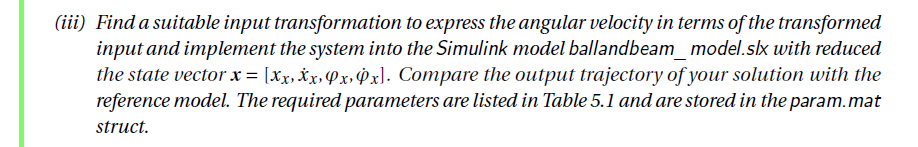

We can simply assign the input as the derivative of the angular velocity x4 (u = x4_dot). In this way, x_dot has to be rewrited as: x_dot = f + g*u

gx = [0; 0; 0; 1]; % avoid confusion with par.g
u = f(4)

$$u = -\frac{2\,\mathrm{mb}\,x_{1}\,x_{2}\,x_{4}-\tau_{x}+g\,\mathrm{mb}\,x_{1}\,\cos\left(x_{3}\right)}{\mathrm{mb}\,{x_{1}}^{2}+\mathrm{Jb}+\mathrm{Jp}}$$

f(4) = 0 % replace the 4th entry with 0

$$f = \left(\begin{array}{c} x_{2}\\ \frac{5\,x_{1}\,{x_{4}}^{2}}{7}-\frac{5\,g\,\sin\left(x_{3}\right)}{7}\\ x_{4}\\ 0 \end{array}\right)$$

% Determine the relative degree
k = 0;
h = x(1); % y = h(x) = x1
lglfh = LgLfh(f,gx,h,x,0);
while lglfh == 0
    k = k+1;
    lglfh = simplify(LgLfh(f,gx,h,x,k));
end

r = k+1 

r = 3

b = LgLfh(f,gx,h,x,k)

$$b = \frac{10\,x_{1}\,x_{4}}{7}$$

Our relative degree is 3, but it can be seen that it is not defined when our states $x_1$ = 0 or $x_4$ = 0

# Exercise 5.2

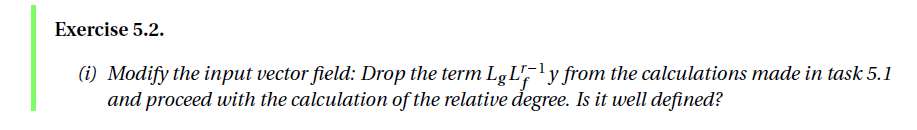

% We can simply drop the term by doing the calculation for the next
% derivative after the last iteration of the previous exercise
k = k+1;
a_1 = simplify(Lfh(f,h,x,4))  

$$a\_1 = \frac{5\,{x_{4}}^{2}\,\left(5\,x_{1}\,{x_{4}}^{2}+2\,g\,\sin\left(x_{3}\right)\right)}{49}$$

b_1 = LgLfh(f,gx,h,x,k)

$$b\_1 = \frac{10\,x_{2}\,x_{4}}{7}-\frac{5\,g\,\cos\left(x_{3}\right)}{7}$$

r_1 = k+1

r_1 = 4

The relative degree this time is 4

Lf2h = Lfh(f,h,x,2)

$$Lf2h = \frac{5\,x_{1}\,{x_{4}}^{2}}{7}-\frac{5\,g\,\sin\left(x_{3}\right)}{7}$$

Next we subtract the critical term

Lf2h_2 = Lf2h - (5/7)*x(1)*(x(4)^2);
Lf3h_2 = jacobian( Lf2h_2, x )*f;

a_2 = jacobian( Lf3h_2, x )*f

$$a\_2 = \frac{5\,g\,{x_{4}}^{2}\,\sin\left(x_{3}\right)}{7}$$

b_2 = jacobian( Lf3h_2, x )*gx 

$$b\_2 = -\frac{5\,g\,\cos\left(x_{3}\right)}{7}$$

The relative degree is 4 here

r_2 = 4;

Lf2h = Lfh(f,h,x,2)

$$Lf2h = \frac{5\,x_{1}\,{x_{4}}^{2}}{7}-\frac{5\,g\,\sin\left(x_{3}\right)}{7}$$

As we have non linear terms so we linearize around 0, for sin( $x_3$ ) ~= $x_3$, for $x_1$ $x_4$^2 around 0 it is ~= 0 

Lf2hlin  = -(5/7)*g*x(3);
Lf3h_3 = jacobian( Lf2hlin, x )*f;
a_3 = jacobian( Lf3h_3, x )*f

$$a\_3 = 0$$

b_3 = jacobian( Lf3h_3, x )*gx 

$$b\_3 = -\frac{5\,g}{7}$$

The relative degree here is also 4

r_3 = 4;

% vector of the reference trajectory and its derivatives
syms y_ref y_ref_dot y_ref_ddot y_ref_3dot y_ref_4dot
ref_traj = [ y_ref; y_ref_dot; y_ref_ddot; y_ref_3dot; y_ref_4dot ];

% coefficients of the hurwitz polynomial
syms p0 p1 p2 p3 p4
p = [ p0; p1; p2; p3; p4; ];

% Vector of our Lf^rh as without modifying from the initial exercise
Lfhv = sym(zeros(5,1)); % preallocate the Lfhv vector
for i = 1:5
    Lfhv(i) = simplify(Lfh(f,h,x,i-1));
end

To construct our control input needed to follow a trajectory

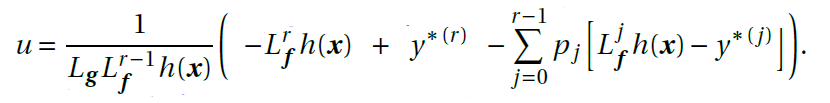

% As we have the Lfh, trajectory derivates, and p components as vectors, we can simply do this summation as a vector subtraction 
% between our Lfh vector and reference trajectory and then element wise multiplication with our p coeffients and summing the resulting vector 
sum_term = sum( p(1:r_1).*( Lfhv(1:r_1) - ref_traj(1:r_1)));
u_1 = simplify((1/b_1)*(-a_1 + ref_traj(r_1+1) - sum_term))

$$u\_1 = \frac{7\,\left(y_{\mathrm{ref},\mathrm{4dot}}+p_{2}\,\left(-\frac{5\,x_{1}\,{x_{4}}^{2}}{7}+y_{\ddot{\mathrm{ref}}}+\frac{5\,g\,\sin\left(x_{3}\right)}{7}\right)+p_{3}\,\left(-\frac{5\,x_{2}\,{x_{4}}^{2}}{7}+\frac{5\,g\,\cos\left(x_{3}\right)\,x_{4}}{7}+y_{\mathrm{ref},\mathrm{3dot}}\right)-p_{0}\,\left(x_{1}-y_{\mathrm{ref}}\right)-p_{1}\,\left(x_{2}-y_{\dot{\mathrm{ref}}}\right)-\frac{5\,{x_{4}}^{2}\,\left(5\,x_{1}\,{x_{4}}^{2}+2\,g\,\sin\left(x_{3}\right)\right)}{49}\right)}{10\,x_{2}\,x_{4}-5\,g\,\cos\left(x_{3}\right)}$$

% For the control input of exercise 2, we have to modify our Lfh vector but
% then it is the same procedure
Lfhv_2 = [ Lfhv(1); Lfhv(2); Lf2h_2; Lf3h_2; a_2];
sum_term = sum( p(1:r_2).*( Lfhv_2(1:r_2) - ref_traj(1:r_2)));
u_2 = simplify((1/b_2)*(-a_2 + ref_traj(r_2+1) - sum_term))

$$u\_2 = -\frac{7\,\left(y_{\mathrm{ref},\mathrm{4dot}}+p_{2}\,\left(y_{\ddot{\mathrm{ref}}}+\frac{5\,g\,\sin\left(x_{3}\right)}{7}\right)-p_{0}\,\left(x_{1}-y_{\mathrm{ref}}\right)-p_{1}\,\left(x_{2}-y_{\dot{\mathrm{ref}}}\right)+p_{3}\,\left(y_{\mathrm{ref},\mathrm{3dot}}+\frac{5\,g\,x_{4}\,\cos\left(x_{3}\right)}{7}\right)-\frac{5\,g\,{x_{4}}^{2}\,\sin\left(x_{3}\right)}{7}\right)}{5\,g\,\cos\left(x_{3}\right)}$$

% Similarly for the 3rd control input
Lfhv_3 = [ Lfhv(1); Lfhv(2); Lf2hlin; Lf3h_3; a_3];
sum_term = sum( p(1:r_3).*( Lfhv_3(1:r_3) - ref_traj(1:r_3)));
u_3 = simplify((1/b_3)*(-a_3 + ref_traj(r_3+1) - sum_term))

$$u\_3 = -\frac{7\,\left(y_{\mathrm{ref},\mathrm{4dot}}-p_{0}\,\left(x_{1}-y_{\mathrm{ref}}\right)-p_{1}\,\left(x_{2}-y_{\dot{\mathrm{ref}}}\right)+p_{3}\,\left(y_{\mathrm{ref},\mathrm{3dot}}+\frac{5\,g\,x_{4}}{7}\right)+p_{2}\,\left(y_{\ddot{\mathrm{ref}}}+\frac{5\,g\,x_{3}}{7}\right)\right)}{5\,g}$$

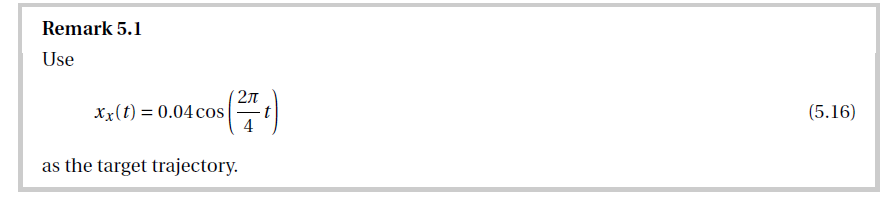

syms t

% Create a vector for the reference trajectory and its derivatives
ref_traj(1) = 0.04*cos( (2*pi/4)*t);
for i = 2:5
    ref_traj(i) = diff(ref_traj(i-1), t);
end
ref_traj

$$ref\_traj = \left(\begin{array}{c} \frac{\cos\left(\frac{\pi \,t}{2}\right)}{25}\\ -\frac{\pi \,\sin\left(\frac{\pi \,t}{2}\right)}{50}\\ -\frac{\pi^{2}\,\cos\left(\frac{\pi \,t}{2}\right)}{100}\\ \frac{\pi^{3}\,\sin\left(\frac{\pi \,t}{2}\right)}{200}\\ \frac{\pi^{4}\,\cos\left(\frac{\pi \,t}{2}\right)}{400} \end{array}\right)$$

# Exercise 5.3

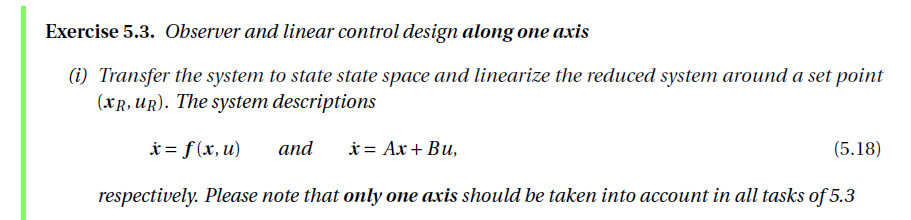

% Our linear system states are x_x, and x_x_dot
xlin = [x1 x2];
% As we assume phi_x_dot << 1, so we can neglect its squared term 
flin = [ f(1); subs(f(2), x4, 0) ];
% If we linearize around U_R small enough, sin(u_R ) ~= u_R
syms u_R
flin = subs( flin, x3, u_R);
% To get the A matrix
A = double(jacobian( flin, xlin ))

A =      0     1
     0     0


% To get the B matrix
B = subs(jacobian( flin, u_R ), u_R, 0)

$$B = \left(\begin{array}{c} 0\\ -\frac{5\,g}{7} \end{array}\right)$$

% To get our C Matrix
y = x1;        
C = double(jacobian( y, xlin ))

C =      1     0


% Construct the controllability matrix
CtrbMatrix = [B A*B]

$$CtrbMatrix = \left(\begin{array}{cc} 0 & -\frac{5\,g}{7}\\ -\frac{5\,g}{7} & 0 \end{array}\right)$$

rank(CtrbMatrix)

ans = 2

% Construct the observability matrix
obsMatrix = [C; C*A]

obsMatrix =      1     0
     0     1


rank(obsMatrix)

ans = 2

As both the controllability matrix and the observability matrix are full rank, then the system is both controllable and observable.

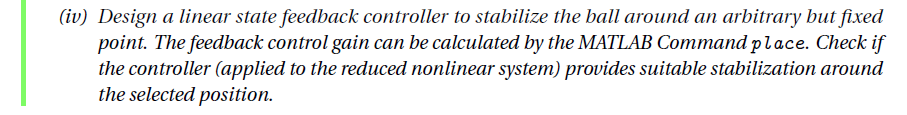

% The desired poles
p = [-3,-5];

% Because place doesn't work with symbolic variables we have to subs the value of g.
Bsubs = double(subs(B, g, par.g));
k = place(A,Bsubs,p)

k =    -2.1407   -1.1417


# Exercise 5.4

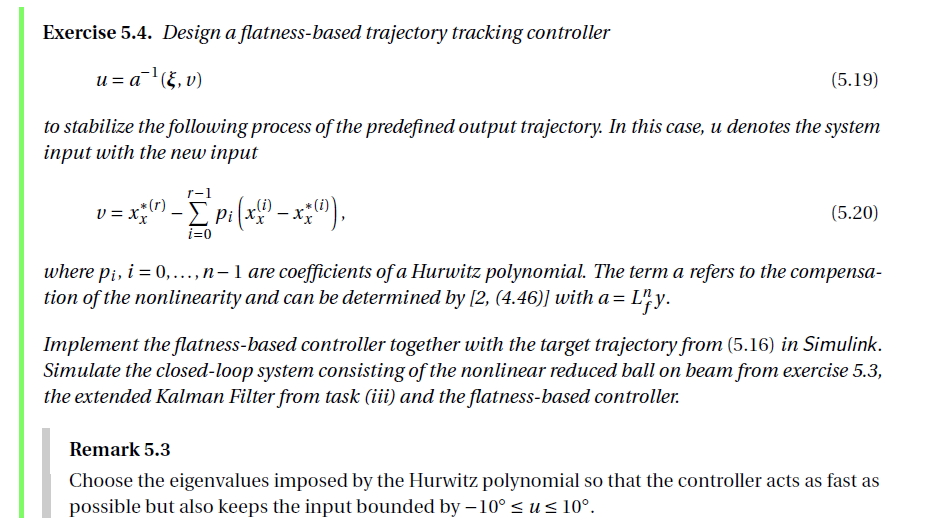

syms u
% by taking our output to be x1
h = x1;

x_reduced = [x1 x2];
f_reduced = [f(1); subs(f(2),[x4 x3],[0 u]); ];
syms xi xi_dot xi_ddot

eq1 = xi == Lfh(f_reduced,h,x_reduced,0 )   % h

$$eq1 = \xi =x_{1}$$

eq2 = xi_dot == Lfh(f_reduced,h,x_reduced,1 )   % xi_dot

$$eq2 = \dot{\xi }=x_{2}$$

eq3 = xi_ddot == Lfh(f_reduced,h,x_reduced,2 )   % xi_ddot

$$eq3 = \ddot{\xi }=-\frac{5\,g\,\sin\left(u\right)}{7}$$

As our control input appears here

u = isolate( eq3, u )

$$u = u=-\mathrm{asin}\left(\frac{7\,\ddot{\xi }}{5\,g}\right)$$